# Generación de series de tiempo para comparación

## Different time series from function

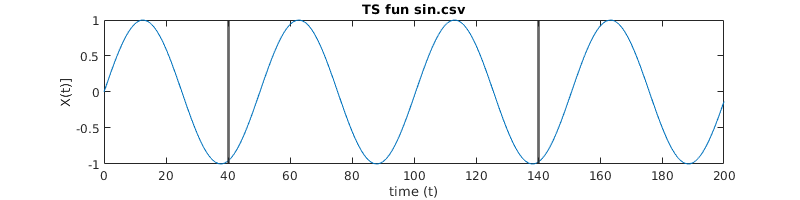

clear all
clc

% Initial conditions
X0 = 0.5;

%---------------------------------------
% Time Information
N = 200; % number of iterations

t = 0:1:N;
%X = ones(201,1)*0.5; ----- Constant
%X = t*0.5; ---- Linear
%X = 0.25*t.^2; ---- Quadratic
%X = 0.1*(t-100).^3; ---- Cubic
%X=sqrt(t-40); ---- Square Root
%X = exp(t/30); ---- Exponential
%X = log(t+1); ---- Logarithm
%X = sin(t/8);

X_noise = X + rand(1,201)*(max(X)-min(X))*0.05;

log_vec = [t',X'];
log_vec_python = log_vec(40:140,:);

log_vec_noise = [t',X_noise'];
log_vec_python_noise = log_vec_noise(40:140,:);

%writematrix(log_vec,'TS_random.txt','Delimiter','tab')
%writematrix(log_vec_python,'TS_fun_constant.csv','Delimiter','comma')

%writematrix(log_vec_python,'TS_fun_sin.csv','Delimiter','comma')
%writematrix(log_vec_python_noise,'TS_fun_sin_noise.csv','Delimiter','comma')

set(gcf, 'Position', [100, 100, 800, 200]);
plot(t,X);
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)
xlabel('time (t)')
ylabel('X(t)]')
title("TS fun sin.csv")

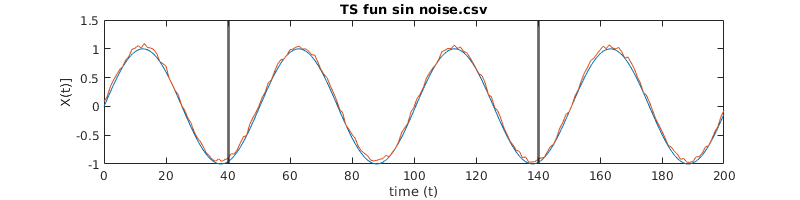


plot(t,[X' X_noise']);
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)
xlabel('time (t)')
ylabel('X(t)]')
title("TS fun sin noise.csv")

## Solving the logistic equation with constant*** r***

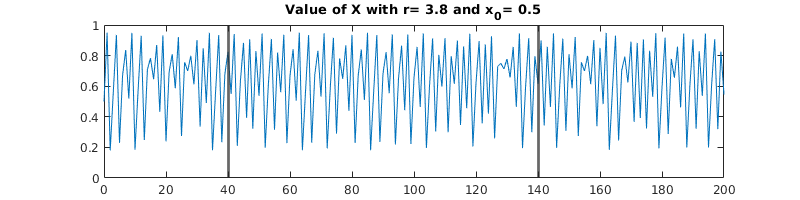

clear all
clc

%---------------------------------------
% Parameters
r0 = 3.8; % Growth rate

%---------------------------------------
% Initial conditions
X0 = 0.5;

%---------------------------------------
% Time Information
N = 200; % number of iterations

r(1) = r0;

%---------------------------------------
% Calculate r
for i=1:1:N+1
    t = (i-1);
    r(i) = r0;
end
%writematrix(r','r_ct.txt');
%writematrix(r','TS_constant.txt');

%---------------------------------------
% Store X0 in solution vector
X(1) = X0;

%---------------------------------------
% Iterate to get solution values
for i=1:1:N
    X(i+1) = r0*X(i)*(1-X(i));
end
X_noise = X + rand(1,201)*(max(X)-min(X))*0.05;
%---------------------------------------
% Plot
% Solution is stored in X; plot against timen

t = 0:1:N; % Store n-Values to plot against

log_vec = [t',X'];
log_vec_python = log_vec(40:140,:);

log_vec_noise = [t',X_noise'];
log_vec_python_noise = log_vec_noise(40:140,:);

%writematrix(log_vec,'logistic_ts_r_ct.txt','Delimiter','tab')
%writematrix(log_vec,'TS_chaos_rcte.txt','Delimiter','tab')
%writematrix(log_vec_python,'TS_chaos_rcte.csv','Delimiter','comma')

writematrix(log_vec_python,'TS_logistic_chaos_rcte.csv','Delimiter','comma')
writematrix(log_vec_python_noise,'TS_logistic_chaos_rcte_noise.csv','Delimiter','comma')

set(gcf, 'Position', [100, 100, 800, 200]);

plot(t,X);
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)
title("Value of X with r= " +r0+ " and x_0= " + X0)

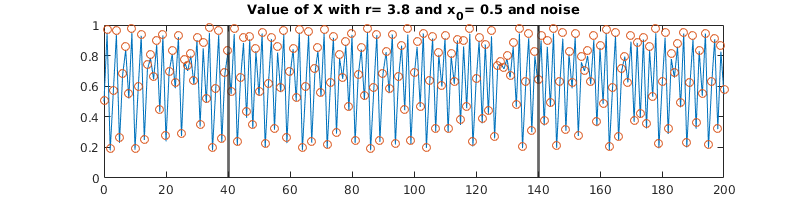

plot(t,X); hold on; plot(t,X_noise, 'o'); hold off
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)
title("Value of X with r= " +r0+ " and x_0= " + X0 + " and noise")

The resulting time series is stored in the file '[logistic_time_series.txt](matlab:open('./logistic_time_series.txt'))'

## Solving the logistic equation with variable*** r(t)***


$$r(t) = r_0 - K \cos \left(  \frac{2 \pi}{T} \right) e^{- \frac{t}{T}}$$


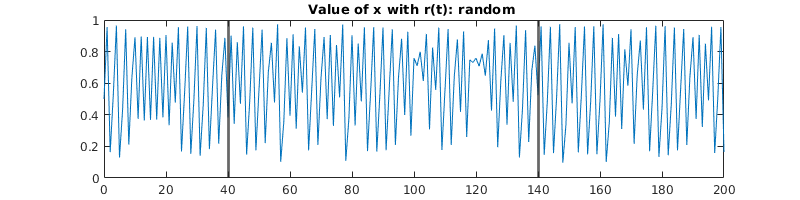

clear all
clc

N = 200; % Numero de iteraciones

% Parameters
T = N/2; % Half of the data points -> N/2
r0 = 3.8;
K = 0.045;

% Initial Conditions
X0 = 0.5;


% Generar nuevo time series

r(1) = r0;

%------------------- Calculate r --------------------
% (proposed by Verdes)
%{
for i=1:1:N+1
    t = (i-1);
    r(i) = r0-K*cos(2*pi*t/T)*exp(-t/T);
end
%}

% (r varia de diferentes formas) (Updated: 2021.10.27)
for i=1:1:N+1
    t = (i-1);
    %r(i) = r0+0.001*i; ---- Linear
    %r(i) = r0+0.000005*i.^2; ---- quadratic
    %r(i) =r0+0.00000001*i.^3; ---- cubic
    %r(i) = r0 + sqrt(i/5000); ---- sqrt
    %r(i) = r0-1 + exp(i/1000); ---- exp
    %r(i) = r0+log(i+1)/50; ---- log
    %r(i) = r0+0.1+sin(i/4)/20; ---- sine
    %r(i) = rand(i);
end
r = r0+rand(N+1,1)*0.1;

%writematrix(r','r_var.txt');
%writematrix(r','r_var_mil.txt');

%---------------------------------------
%dat = load('r.txt');
%---------------------------------------
% Store X0 in solution vector
X(1) = X0;

%---------------------------------------
% Iterate to get solution values
for i=1:1:N
    X(i+1) = r(i)*X(i)*(1-X(i));
end
X_noise = X + rand(1,201)*(max(X)-min(X))*0.05;

t = 0:1:N;
t = t';

log_vec = [t,X'];
log_vec_python = log_vec(40:140,:);

log_vec_noise = [t,X_noise'];
log_vec_python_noise = log_vec_noise(40:140,:);

%writematrix(log_vec,'logistic_ts_r_var.txt','Delimiter','tab')
%writematrix(log_vec,'TS_chaos_rvar.txt','Delimiter','tab')

%writematrix(log_vec_python,'TS_chaos_rverdes.csv','Delimiter','comma')

writematrix(log_vec_python,'TS_logistic_chaos_rvar8.csv','Delimiter','comma')
writematrix(log_vec_python_noise,'TS_logistic_chaos_rvar8_noise.csv','Delimiter','comma')


%---------------------------------------
% Plot
% Solution is stored in X; plot against timen
    
%log_vec = [t',X'];

% Exportar matriz a archivo
%writematrix(log_vec,'logistic_time_series.txt','Delimiter','tab')

plot(t,X);
title("Value of x with r(t): random ")
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)

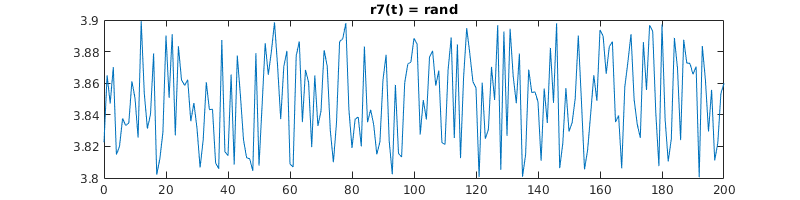


plot(t,r)
title('r7(t) = rand')

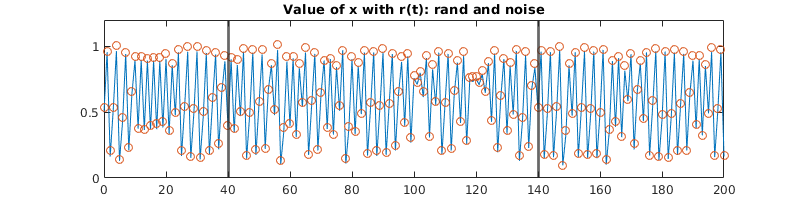


plot(t,X); hold on; plot(t,X_noise, 'o'); hold off
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)
title("Value of x with r(t): rand and noise")

## Generating a TS with random values

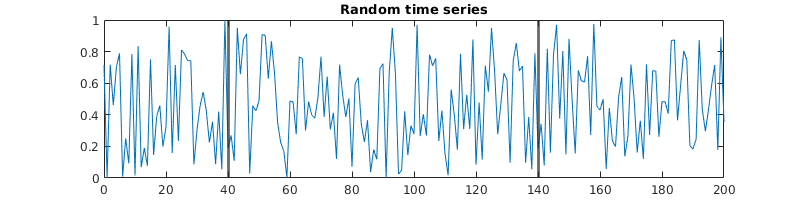

clear all
clc

N=200;
X = rand(N+1,1);
t = 0:1:N;
t = t';
log_vec = [t,X];
log_vec_python = log_vec(40:140,:);

%writematrix(log_vec,'TS_random.txt','Delimiter','tab')
writematrix(log_vec_python,'TS_random.csv','Delimiter','comma')


plot(t,X);
title("Random time series")
xline(40, 'LineWidth', 2)
xline(140, 'LineWidth', 2)

## Results of this program (Outdated)

- `txt` file: Time series $x(t)$ of the logistic map with $r = \mathrm{ct.}$ --> [`logistic_ts_r_ct.txt`](matlab:open('./logistic_ts_r_ct.txt'))

- `txt` file: Time series $x(t)$ of the logistic map with $r(t)$ --> [`logistic_ts_r_var.txt`](matlab:open('./logistic_ts_r_var.txt'))

- txt file: Time series $r(t)$ --> [`r.txt`](matlab:open('./r.txt'))